% Charger les solutions depuis le fichier
load('solutions.mat');
% Afficher toutes les configurations trouvées en radian
disp('Configurations possibles du robot pour la position désirée :');

Configurations possibles du robot pour la position désirée :


disp('    Theta1   Theta2    Theta3    Theta4    Theta5  X_calculé   Y_calculé');

    Theta1   Theta2    Theta3    Theta4    Theta5  X_calculé   Y_calculé


disp(all_solutions);  

    5.4319    0.7383    1.6078    5.5231    2.1504    4.0000    2.0000
    5.2879    1.8450    3.0631    2.8400    0.8062    4.0000    2.0000
    5.9721    0.5659    1.4071    0.2832    2.8203    4.0000    2.0000
    0.8722    4.6387    2.6470    3.6895    2.4614    4.0000    2.0000



    

% Convertion des angles de radians en degrés et afficher les résultats
all_solutions_deg = rad2deg(all_solutions(:, 1:5));
% Afficher toutes les configurations trouvées en degrrs
disp('Configurations possibles du robot pour la position désirée :');

Configurations possibles du robot pour la position désirée :


disp('    Theta1°   Theta2°   Theta3°   Theta4°  Theta5°   X_calculé   Y_calculé')

    Theta1°   Theta2°   Theta3°   Theta4°  Theta5°   X_calculé   Y_calculé


disp([all_solutions_deg, all_solutions(:, 6:7)]);

  311.2261   42.3037   92.1204  316.4493  123.2095    4.0000    2.0000
  302.9727  105.7101  175.5038  162.7193   46.1916    4.0000    2.0000
  342.1754   32.4239   80.6199   16.2277  161.5934    4.0000    2.0000
   49.9760  265.7766  151.6625  211.3913  141.0282    4.0000    2.0000



 

% Convertir les angles en radians et ajuster les angles à l'intervalle [-180, 180]
all_solutions_deg = mod(all_solutions_deg + 180, 360) - 180;
% Afficher toutes les configurations trouvées avec les angles ajustés
disp('Configurations possibles du robot pour la position désirée (dans lintervalle [-180, 180]) :');

Configurations possibles du robot pour la position désirée (dans lintervalle [-180, 180]) :


disp('    Theta1°   Theta2°   Theta3°   Theta4°   Theta5°   X_calculé   Y_calculé');

    Theta1°   Theta2°   Theta3°   Theta4°   Theta5°   X_calculé   Y_calculé


disp([all_solutions_deg, all_solutions(:, 6:7)]);

  -48.7739   42.3037   92.1204  -43.5507  123.2095    4.0000    2.0000
  -57.0273  105.7101  175.5038  162.7193   46.1916    4.0000    2.0000
  -17.8246   32.4239   80.6199   16.2277  161.5934    4.0000    2.0000
   49.9760  -94.2234  151.6625 -148.6087  141.0282    4.0000    2.0000




% Filtrer les solutions en fonction des butees
filtered_solutions_indices = all((all_solutions_deg(:, 1:5) >= min_angle) & (all_solutions_deg(:, 1:5) <= max_angle), 2);
filtered_solutions = all_solutions(filtered_solutions_indices, :);
    
% Afficher toutes les configurations filtrées
disp('Configurations possibles du robot pour la position désirée (dans les bornes dangles specifiees) :');

Configurations possibles du robot pour la position désirée (dans les bornes dangles specifiees) :


disp('    Theta1°   Theta2°   Theta3°   Theta4°   Theta5°   X_calculé   Y_calculé');

    Theta1°   Theta2°   Theta3°   Theta4°   Theta5°   X_calculé   Y_calculé


disp([filtered_solutions(:, 1:5), filtered_solutions(:, 6:7)]);



## **Affichage de l'espace de solutions**

#### **Variation de theta pour chaque solution**

% Définir le nombre total de solutions
num_solutions = size(all_solutions, 1);
% Définir le nombre de lignes et de colonnes pour la grille
num_rows = 3; % Modifier le nombre de lignes selon le nombre de joints
num_cols = 2; % Nombre de colonnes pour afficher les graphiques
% Définir les positions des subplots
position = reshape(1:num_rows*num_cols, num_cols, num_rows).';

% Convertir les angles en degrés et ajuster les angles à l'intervalle [-180, 180]
all_solutions_deg = rad2deg(all_solutions(:, 1:5));
all_solutions_deg = mod(all_solutions_deg + 180, 360) - 180;

% Créer une nouvelle figure
figure;

% Boucle sur chaque angle d'articulation
for joint = 1:5
    % Définir la position du subplot dans la grille
    subplot(num_rows, num_cols, joint);
    
    % Titre et étiquettes des axes
    title(['Variation de Theta', num2str(joint), ' pour chaque solution']);
    xlabel('Solution');
    ylabel(['Theta', num2str(joint), '°']); % Modification de l'étiquette en degrés
    grid on;

    hold on; % Garder le graphique actif pour ajouter les données de chaque solution

    % Tracer les valeurs des angles d'articulation pour chaque solution
    for i = 1:num_solutions
        % Extraire l'angle d'articulation ajusté pour cette solution
        theta_deg = all_solutions_deg(i, joint);

        % Tracer l'angle d'articulation pour cette solution
        plot(i, theta_deg, '+', 'MarkerSize', 5, 'LineWidth', 1, 'Color', 'k','HandleVisibility', 'off');
    end

    % Calculer une interpolation linéaire des données
    x_data = 1:num_solutions; % Les données x sont simplement les indices des solutions
    y_data = all_solutions_deg(:, joint); % Les données y sont les angles d'articulation déjà ajustés

    % Définir un ensemble de points plus fins pour l'interpolation
    finer_x = linspace(1, num_solutions, 1000); % 1000 points entre le premier et le dernier index

    % Calculer les valeurs interpolées
    interpolated_1 = interp1(x_data, y_data, finer_x, 'spline');
    interpolated_2 = interp1(x_data, y_data, finer_x, 'linear');

    % Tracer la courbe d'interpolation
    plot(finer_x, interpolated_1, 'r-', 'LineWidth', 1, 'DisplayName', 'Interpolation Spline');
    plot(finer_x, interpolated_2, 'k-', 'LineWidth', 1, 'DisplayName', 'Interpolation Lineaire');

    % Trouver la valeur maximale et minimale de theta pour cet angle d'articulation
    max_theta = max(all_solutions_deg(:, joint));
    min_theta = min(all_solutions_deg(:, joint));
    
    % Ajouter du texte à la position souhaitée
    text(-1, max_theta, ['Max: ', num2str(max_theta)], 'Color', 'blue', 'FontSize', 8);
    text(-1, min_theta, ['Min: ', num2str(min_theta)], 'Color', 'blue', 'FontSize', 8);
    disp(['Pour l''angle ', num2str(joint), ', Theta max : ', num2str(max_theta), ', Theta min : ', num2str(min_theta)]);

    % Tracer une droite représentant la valeur maximale de theta pour cet angle d'articulation
    plot([1, num_solutions], [max_theta, max_theta], '-b', 'LineWidth', 0.6, 'DisplayName', ['Max Theta', num2str(joint)]);

    % Tracer une droite représentant la valeur minimale de theta pour cet angle d'articulation
    plot([1, num_solutions], [min_theta, min_theta], '-b', 'LineWidth', 0.6, 'DisplayName', ['Min Theta', num2str(joint)]);
      
end

Pour l'angle 1, Theta max : 49.976, Theta min : -57.0273
Pour l'angle 2, Theta max : 105.7101, Theta min : -94.2234
Pour l'angle 3, Theta max : 175.5038, Theta min : 80.6199
Pour l'angle 4, Theta max : 162.7193, Theta min : -148.6087
Pour l'angle 5, Theta max : 161.5934, Theta min : 46.1916


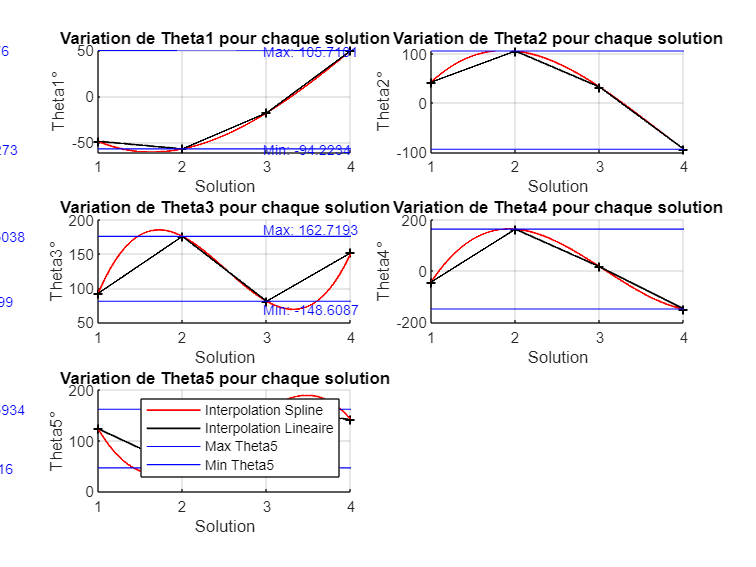


% Légende
legend('show');

#### Courbe des angles pour chaque solution - interpolation

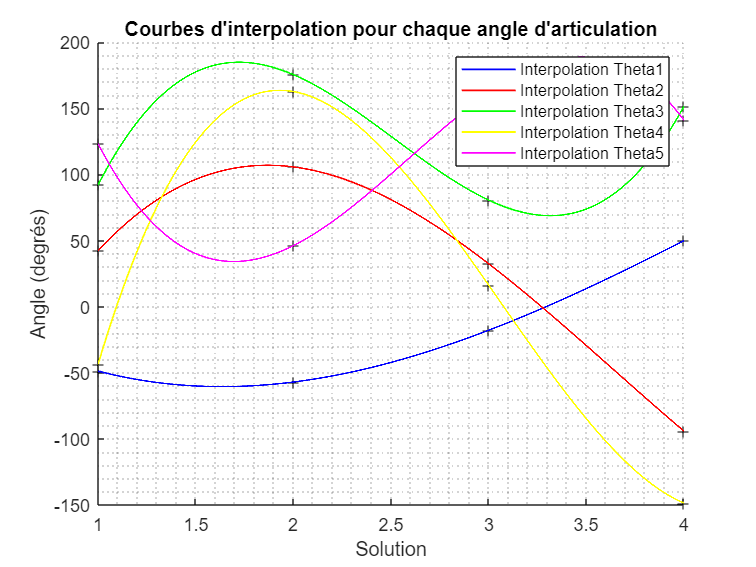

%Courbe de chaque angles 
% Créer une nouvelle figure
figure;

% Titre et étiquettes des axes
title('Courbes d''interpolation pour chaque angle d''articulation');
xlabel('Solution');
ylabel('Angle (degrés)');
grid minor;
hold on; % Garder le graphique actif pour ajouter les données de chaque solution

% Boucle sur chaque angle d'articulation
for joint = 1:5
    % Tracer les valeurs des angles d'articulation pour chaque solution en convertissant les radians en degrés
    for i = 1:num_solutions
        % Extraire l'angle d'articulation ajusté pour cette solution
        theta_deg = all_solutions_deg(i, joint);
        % Tracer l'angle d'articulation pour cette solution avec un marqueur plein
        plot(i, theta_deg, '+', 'MarkerFaceColor', 'k', 'MarkerEdgeColor', 'k', 'HandleVisibility', 'off');

    end
    
    % Calculer une interpolation linéaire des données
    x_data = 1:num_solutions; % Les données x sont simplement les indices des solutions
    y_data = all_solutions_deg(:, joint); % Les données y sont les angles d'articulation convertis en degrés
    
    % Définir un ensemble de points plus fins pour l'interpolation
    finer_x = linspace(1, num_solutions, 10000); % 1000 points entre le premier et le dernier index
    
    % Calculer les valeurs interpolées
    interpolated_y = interp1(x_data, y_data, finer_x, 'spline');
    
    % Couleurs pour chaque angle d'articulation
    colors = ['b', 'r', 'g', 'y', 'm'];
    
    % Tracer la courbe d'interpolation
    plot(finer_x, interpolated_y, '-', 'DisplayName', ['Interpolation Theta', num2str(joint)], 'LineWidth', 1, 'Color', colors(joint));
end
        
legend("show")  

#### Positions de des articulations pour chaque solution

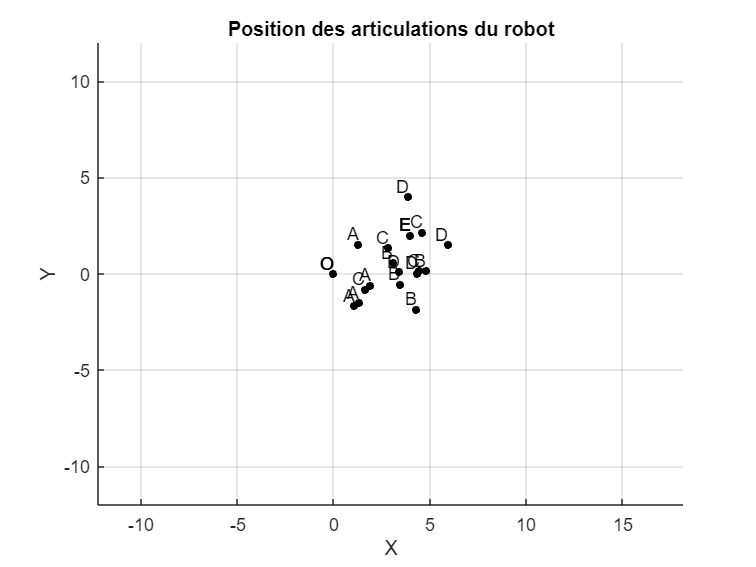

% Créer un graphique distinct pour les articulations du robot
figure;


% Titre et étiquettes des axes
title('Configurations du robot à 4 articulations');
xlabel('Position X');
ylabel('Position Y');

hold on; % Garder le graphique actif pour ajouter les données de chaque solution


% Visualisation des configurations du robot
for i = 1:size(all_solutions, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = all_solutions(i, 1);
    theta2 = all_solutions(i, 2);
    theta3 = all_solutions(i, 3);
    theta4 = all_solutions(i, 4);
    theta5 = all_solutions(i, 5);

    % Calcul des positions des articulations du robot avec les valeurs des angles d'articulation calculées
    O = [0, 0]; % Position de l'origine
    A = [a1*cos(theta1), a1*sin(theta1)]; % Position de l'articulation A
    B = A + [a2*cos(theta1+theta2), a2*sin(theta1+theta2)]; % Position de l'articulation B
    C = B + [a3*cos(theta1+theta2+theta3), a3*sin(theta1+theta2+theta3)]; % Position de l'articulation C (extrémité de l'effecteur)
    D = C + [a4*cos(theta1+theta2+theta3+theta4), a4*sin(theta1+theta2+theta3+theta4)]; % Position de l'articulation C (extrémité de l'effecteur)
    E = D + [a5*cos(theta1+theta2+theta3+theta4+theta5), a5*sin(theta1+theta2+theta3+theta4+theta5)]; % Position de l'articulation C (extrémité de l'effecteur)

    % Tracer le robot pour cette configuration 
    scatter([O(1), A(1), B(1), C(1), D(1), E(1)], [O(2), A(2), B(2), C(2), D(2), E(2)], 20, 'k', 'filled', 'DisplayName', ['Articulations - Solution ', num2str(i)]); % Marques pour les articulations
    % Ajouter les noms des articulations
    text([O(1), A(1), B(1), C(1), D(1), E(1)], [O(2), A(2), B(2), C(2), D(2), E(2)], {'O', 'A', 'B', 'C', 'D', 'E'}, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end 
grid on;

% Calculer les limites des axes
xlim([-12, 12]); 
ylim([-12, 12]);
axis equal

% Configurer le titre et les étiquettes des axes
title('Position des articulations du robot');
xlabel('X');
ylabel('Y');

#### Graphique separe pour chaque articulation

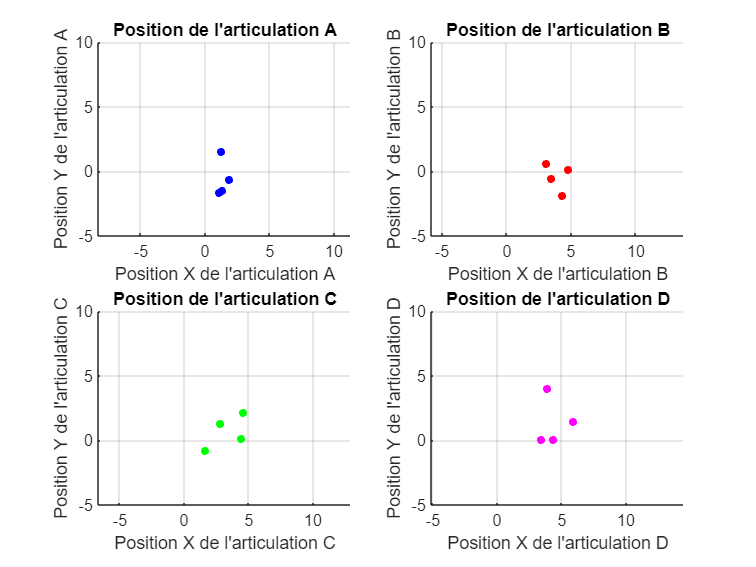

% Créer un graphique distinct pour chaque articulation
figure;

% Articulation A
subplot(2, 2, 1);
title('Position de l''articulation A');
xlabel('Position X de l''articulation A');
ylabel('Position Y de l''articulation A');
hold on;
% Calculer les positions de l'articulation A pour chaque solution
A_positions = zeros(size(all_solutions, 1), 2);
for i = 1:size(all_solutions, 1)
    % Extraire l'angle d'articulation pour cette configuration
    theta1 = all_solutions(i, 1);
    
    % Calculer la position de l'articulation A pour cette solution
    A = [a1*cos(theta1), a1*sin(theta1)]; % Position de l'articulation A
    A_positions(i, :) = A;
end
scatter(A_positions(:, 1), A_positions(:, 2), 20, 'b', 'filled');
grid on;
xlim([-5, 5]); % Définir les limites des axes X
ylim([-5, 10]); % Définir les limites des axes Y

% Articulation B
subplot(2, 2, 2);
title('Position de l''articulation B');
xlabel('Position X de l''articulation B');
ylabel('Position Y de l''articulation B');
hold on;
% Calculer les positions de l'articulation B pour chaque solution
B_positions = zeros(size(all_solutions, 1), 2);
for i = 1:size(all_solutions, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = all_solutions(i, 1);
    theta2 = all_solutions(i, 2);
    
    % Calculer la position de l'articulation B pour cette solution
    B = A_positions(i, :) + [a2*cos(theta1+theta2), a2*sin(theta1+theta2)]; % Position de l'articulation B
    B_positions(i, :) = B;
end
scatter(B_positions(:, 1), B_positions(:, 2), 20, 'r', 'filled');
grid on;
xlim([-5, 5]); % Définir les limites des axes X
ylim([-5, 10]); % Définir les limites des axes Y

% Articulation C
subplot(2, 2, 3);
title('Position de l''articulation C');
xlabel('Position X de l''articulation C');
ylabel('Position Y de l''articulation C');
hold on;
% Calculer les positions de l'articulation C pour chaque solution
C_positions = zeros(size(all_solutions, 1), 2);
for i = 1:size(all_solutions, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = all_solutions(i, 1);
    theta2 = all_solutions(i, 2);
    theta3 = all_solutions(i, 3);
    
    % Calculer la position de l'articulation C pour cette solution
    C = B_positions(i, :) + [a3*cos(theta1+theta2+theta3), a3*sin(theta1+theta2+theta3)]; % Position de l'articulation C
    C_positions(i, :) = C;
end
scatter(C_positions(:, 1), C_positions(:, 2), 20, 'g', 'filled');
grid on;
xlim([-5, 5]); % Définir les limites des axes X
ylim([-5, 10]); % Définir les limites des axes Y

% Articulation D
subplot(2, 2, 4);
title('Position de l''articulation D');
xlabel('Position X de l''articulation D');
ylabel('Position Y de l''articulation D');
hold on;
% Calculer les positions de l'articulation D pour chaque solution
D_positions = zeros(size(all_solutions, 1), 2);
for i = 1:size(all_solutions, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = all_solutions(i, 1);
    theta2 = all_solutions(i, 2);
    theta3 = all_solutions(i, 3);
    theta4 = all_solutions(i, 4);
    
    % Calculer la position de l'articulation D pour cette solution
    D = C_positions(i, :) + [a4*cos(theta1+theta2+theta3+theta4), a4*sin(theta1+theta2+theta3+theta4)]; % Position de l'articulation D
    D_positions(i, :) = D;
end
scatter(D_positions(:, 1), D_positions(:, 2), 20, 'm', 'filled');
grid on;
xlim([-5, 5]); % Définir les limites des axes X
ylim([-5, 10]); % Définir les limites des axes Y

% Réglage des espacements entre les sous-graphiques
subplot(2, 2, 1); axis equal; 
subplot(2, 2, 2); axis equal; 
subplot(2, 2, 3); axis equal; 
subplot(2, 2, 4); axis equal;

% % Définir le nombre total de solutions
% num_solutions = size(all_solutions, 1);
% 
% % Boucle sur chaque articulation
% for joint = 1:5
%     % Créer une nouvelle figure pour chaque articulation
%     figure;
% 
%     % Titre et étiquettes des axes
%     title(['Positions de l''articulation ', num2str(joint)]);
%     xlabel('X');
%     ylabel('Y');
%     grid on;
% 
%     hold on; % Garder le graphique actif pour ajouter les données de chaque solution
% 
%     % Tracer les positions des articulations pour chaque solution
%     for i = 1:num_solutions
%         % Extraire les coordonnées de l'articulation pour cette solution
%         x_joint = all_solutions(i, 6); % Coordonnée X de l'articulation
%         y_joint = all_solutions(i, 7); % Coordonnée Y de l'articulation
% 
%         % Tracer la position de l'articulation pour cette solution
%         scatter(x_joint, y_joint, 100, 'filled', 'DisplayName', ['Solution ', num2str(i)]);
%     end
% 
%     % Légende
%     legend('Location', 'best');
% end
% Pour l'articulation A

% Pour l'articulation A

% Créer un graphique distinct pour l'articulation A
% figure;

% 
% % Créer un graphique distinct pour chaque solution
% for i = 1:size(all_solutions, 1)
%     % Créer une nouvelle figure pour chaque solution
%     figure;
% 
%     % Extraire les angles d'articulation pour cette configuration
%     theta1 = all_solutions(i, 1);
%     theta2 = all_solutions(i, 2);
%     theta3 = all_solutions(i, 3);
%     theta4 = all_solutions(i, 4);
%     theta5 = all_solutions(i, 5);
% 
%     % Calculer les positions des articulations pour cette configuration
%     O = [0, 0]; % Position de l'origine
%     A = [a1*cos(theta1), a1*sin(theta1)]; % Position de l'articulation A
%     B = A + [a2*cos(theta1+theta2), a2*sin(theta1+theta2)]; % Position de l'articulation B
%     C = B + [a3*cos(theta1+theta2+theta3), a3*sin(theta1+theta2+theta3)]; % Position de l'articulation C
%     D = C + [a4*cos(theta1+theta2+theta3+theta4), a4*sin(theta1+theta2+theta3+theta4)]; % Position de l'articulation D
%     E = D + [a5*cos(theta1+theta2+theta3+theta4+theta5), a5*sin(theta1+theta2+theta3+theta4+theta5)]; % Position de l'articulation E
% 
%     % Tracer les positions des articulations pour cette solution
%     plot([O(1), A(1), B(1), C(1), D(1), E(1)], [O(2), A(2), B(2), C(2), D(2), E(2)], 'o-', 'DisplayName', ['Solution ', num2str(i)]);
% 
%     % Configurer le titre et les étiquettes des axes
%     title(['Positions des articulations pour la solution ', num2str(i)]);
%     xlabel('Position X');
%     ylabel('Position Y');
%     legend('Location', 'best');
%     grid on;
% end
% 

